## Create Image Datastore

clc;
clear; 

imageSize = [224 224];

imds = imageDatastore("Train\", "IncludeSubfolders",true, "LabelSource","foldernames");
[trainSet, testSet] = splitEachLabel(imds, 0.85, 0.15)

trainSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_1.png';
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_10.png';
                              ' ...\Desktop\DATI_new\Train\Adversarial\subject_100_fingerprint_2.png'
                               ... and 3159 more
                              }
                     Folders: {
                              'C:\Users\ccesa\Desktop\DATI_new\Train'
                              }
                      Labels: [Adversarial; Adversarial; Adversarial ... and 3159 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: 

testSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_7.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_8.png';
                              ' ...\ccesa\Desktop\DATI_new\Train\Adversarial\subject_75_fingerprint_9.png'
                               ... and 555 more
                              }
                     Folders: {
                              'C:\Users\ccesa\Desktop\DATI_new\Train'
                              }
                      Labels: [Adversarial; Adversarial; Adversarial ... and 555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                   


Train_aug = augmentedImageDatastore(imageSize,trainSet);
Test_aug = augmentedImageDatastore(imageSize,testSet);

numClasses = numel(categories(trainSet.Labels));

## Network definition

net = resnet50;
%analyzeNetwork(net)
%net.Layers

lgraph = layerGraph(net);

fc = fullyConnectedLayer(2,"Name","new_fc")

fc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"fc1000",fc)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}



out = classificationLayer("Name","new_out")

out =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"ClassificationLayer_fc1000",out)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'new_out'}


## Training Option

batch_size = 16;
Max_epochs = 5;
IterForEpoch = 16

IterForEpoch = 16


options = trainingOptions('adam', ...
    'Plots','training-progress',...
    "Verbose", true, ...
    "VerboseFrequency", 10,...
    "MaxEpochs", Max_epochs,...
    "MiniBatchSize", batch_size,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",IterForEpoch,...
    "InitialLearnRate", 0.0005,...
    "LearnRateSchedule","none", ...
    "L2Regularization", 0.0001,...
    "ExecutionEnvironment","auto")

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 5.0000e-04
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.1000
           LearnRateDropPeriod: 10
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 5
                 MiniBatchSize: 16
                       Verbose: 1
              VerboseFrequency: 10
                ValidationData: []
           ValidationFrequency: 16
            ValidationPatience: Inf
                       Shuffle: 'every-epoch'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 't

## Training Step

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:08 |       56.25% |       0.8193 |          0.0005 |


|       1 |          10 |       00:01:06 |       56.25% |       0.8983 |          0.0005 |


|       1 |          20 |       00:02:10 |       81.25% |       0.4621 |          0.0005 |


|       1 |          30 |       00:03:18 |       81.25% |       0.6892 |          0.0005 |


|       1 |          40 |       00:04:24 |       87.50% |       0.4472 |          0.0005 |


|       1 |          50 |       00:05:28 |       81.25% |       0.3805 |          0.0005 |


|       1 |          60 |       00:06:36 |       68.75% |       0.5111 |          0.0005 |


|       1 |          70 |       00:07:41 |       81.25% |       0.3705 |          0.0005 |


|       1 |          80 |       00:08:45 |       81.25% |       0.5962 |          0.0005 |


|       1 |          90 |       00:09:49 |       87.50% |       0.3840 |          0.0005 |


|       1 |         100 |       00:10:54 |       87.50% |       0.2894 |          0.0005 |


|       1 |         110 |       00:11:58 |       81.25% |       0.2524 |          0.0005 |


|       1 |         120 |       00:13:01 |       81.25% |       0.4021 |          0.0005 |


|       1 |         130 |       00:14:02 |      100.00% |       0.0171 |          0.0005 |


|       1 |         140 |       00:15:06 |       75.00% |       0.4903 |          0.0005 |


|       1 |         150 |       00:16:06 |      100.00% |       0.0647 |          0.0005 |


|       1 |         160 |       00:17:07 |       93.75% |       0.1215 |          0.0005 |


|       1 |         170 |       00:18:08 |       93.75% |       0.0902 |          0.0005 |


|       1 |         180 |       00:19:08 |      100.00% |       0.0590 |          0.0005 |


|       1 |         190 |       00:20:08 |       87.50% |       0.2380 |          0.0005 |


|       2 |         200 |       00:21:09 |       87.50% |       0.1517 |          0.0005 |


|       2 |         210 |       00:22:09 |       93.75% |       0.1035 |          0.0005 |


|       2 |         220 |       00:23:10 |       93.75% |       0.1827 |          0.0005 |


|       2 |         230 |       00:24:10 |       93.75% |       0.1856 |          0.0005 |


|       2 |         240 |       00:25:15 |       93.75% |       0.1630 |          0.0005 |


|       2 |         250 |       00:26:21 |      100.00% |       0.0583 |          0.0005 |


|       2 |         260 |       00:27:28 |      100.00% |       0.0240 |          0.0005 |


|       2 |         270 |       00:28:29 |       93.75% |       0.2280 |          0.0005 |


|       2 |         280 |       00:29:29 |      100.00% |       0.0646 |          0.0005 |


|       2 |         290 |       00:30:29 |      100.00% |       0.0265 |          0.0005 |


|       2 |         300 |       00:31:29 |      100.00% |       0.0790 |          0.0005 |


|       2 |         310 |       00:32:28 |      100.00% |       0.0160 |          0.0005 |


|       2 |         320 |       00:33:28 |      100.00% |       0.0246 |          0.0005 |


|       2 |         330 |       00:34:27 |       93.75% |       0.1057 |          0.0005 |


|       2 |         340 |       00:35:27 |      100.00% |       0.0108 |          0.0005 |


|       2 |         350 |       00:36:27 |      100.00% |       0.0187 |          0.0005 |


|       2 |         360 |       00:37:27 |      100.00% |       0.0495 |          0.0005 |


|       2 |         370 |       00:38:33 |      100.00% |       0.0327 |          0.0005 |


|       2 |         380 |       00:39:33 |      100.00% |       0.0039 |          0.0005 |


|       2 |         390 |       00:40:32 |       87.50% |       0.1375 |          0.0005 |


|       3 |         400 |       00:41:31 |      100.00% |       0.0191 |          0.0005 |


|       3 |         410 |       00:42:31 |      100.00% |       0.0206 |          0.0005 |


|       3 |         420 |       00:43:30 |      100.00% |       0.0085 |          0.0005 |


|       3 |         430 |       00:44:30 |      100.00% |       0.0056 |          0.0005 |


|       3 |         440 |       00:45:31 |      100.00% |       0.0162 |          0.0005 |


|       3 |         450 |       00:46:30 |      100.00% |       0.0004 |          0.0005 |


|       3 |         460 |       00:47:30 |      100.00% |       0.0019 |          0.0005 |


|       3 |         470 |       00:48:30 |       93.75% |       0.1008 |          0.0005 |


|       3 |         480 |       00:49:30 |      100.00% |       0.0014 |          0.0005 |


|       3 |         490 |       00:50:29 |      100.00% |       0.0386 |          0.0005 |


|       3 |         500 |       00:51:28 |      100.00% |       0.0088 |          0.0005 |


|       3 |         510 |       00:52:28 |      100.00% |       0.0130 |          0.0005 |


|       3 |         520 |       00:53:32 |      100.00% |       0.0057 |          0.0005 |


|       3 |         530 |       00:54:34 |      100.00% |       0.0005 |          0.0005 |


|       3 |         540 |       00:55:33 |      100.00% |       0.0003 |          0.0005 |


|       3 |         550 |       00:56:33 |      100.00% |       0.0072 |          0.0005 |


|       3 |         560 |       00:57:32 |      100.00% |       0.0005 |          0.0005 |


|       3 |         570 |       00:58:32 |      100.00% |       0.0003 |          0.0005 |


|       3 |         580 |       00:59:31 |       93.75% |       0.4305 |          0.0005 |


|       3 |         590 |       01:00:31 |      100.00% |       0.0007 |          0.0005 |


|       4 |         600 |       01:01:30 |      100.00% |       0.0176 |          0.0005 |


|       4 |         610 |       01:02:31 |      100.00% |       0.0073 |          0.0005 |


|       4 |         620 |       01:03:30 |      100.00% |       0.0060 |          0.0005 |


|       4 |         630 |       01:04:30 |      100.00% |       0.0127 |          0.0005 |


|       4 |         640 |       01:05:29 |      100.00% |       0.0060 |          0.0005 |


|       4 |         650 |       01:06:28 |      100.00% |       0.0013 |          0.0005 |


|       4 |         660 |       01:07:28 |      100.00% |       0.0052 |          0.0005 |


|       4 |         670 |       01:08:27 |      100.00% |       0.0002 |          0.0005 |


|       4 |         680 |       01:09:27 |      100.00% |       0.0086 |          0.0005 |


|       4 |         690 |       01:10:26 |      100.00% |       0.0472 |          0.0005 |


|       4 |         700 |       01:11:26 |      100.00% |       0.0003 |          0.0005 |


|       4 |         710 |       01:12:25 |      100.00% |       0.0004 |          0.0005 |


|       4 |         720 |       01:13:24 |      100.00% |       0.0018 |          0.0005 |


|       4 |         730 |       01:14:24 |      100.00% |       0.0130 |          0.0005 |


|       4 |         740 |       01:15:23 |      100.00% |       0.0064 |          0.0005 |


|       4 |         750 |       01:16:23 |      100.00% |       0.0005 |          0.0005 |


|       4 |         760 |       01:17:22 |      100.00% |       0.0184 |          0.0005 |


|       4 |         770 |       01:18:22 |      100.00% |       0.0001 |          0.0005 |


|       4 |         780 |       01:19:22 |      100.00% |       0.0073 |          0.0005 |


|       5 |         790 |       01:20:21 |      100.00% |       0.0012 |          0.0005 |


|       5 |         800 |       01:21:21 |      100.00% |       0.0016 |          0.0005 |


|       5 |         810 |       01:22:21 |      100.00% |       0.0040 |          0.0005 |


|       5 |         820 |       01:23:20 |      100.00% |       0.0052 |          0.0005 |


|       5 |         830 |       01:24:20 |      100.00% |       0.0211 |          0.0005 |


|       5 |         840 |       01:25:19 |      100.00% |       0.0003 |          0.0005 |


|       5 |         850 |       01:26:19 |      100.00% |       0.0024 |          0.0005 |


|       5 |         860 |       01:27:18 |      100.00% |       0.0181 |          0.0005 |


|       5 |         870 |       01:28:18 |       93.75% |       0.0595 |          0.0005 |


|       5 |         880 |       01:29:17 |      100.00% |       0.0003 |          0.0005 |


|       5 |         890 |       01:30:16 |      100.00% |       0.0004 |          0.0005 |


|       5 |         900 |       01:31:16 |      100.00% |       0.0007 |          0.0005 |


|       5 |         910 |       01:32:15 |      100.00% |       0.0028 |          0.0005 |


|       5 |         920 |       01:33:14 |      100.00% |       0.0004 |          0.0005 |


|       5 |         930 |       01:34:14 |      100.00% |       0.0805 |          0.0005 |


|       5 |         940 |       01:35:13 |      100.00% |       0.0002 |          0.0005 |


|       5 |         950 |       01:36:13 |      100.00% |       0.0240 |          0.0005 |


|       5 |         960 |       01:37:12 |      100.00% |       0.0020 |          0.0005 |


|       5 |         970 |       01:38:11 |      100.00% |       0.0120 |          0.0005 |


|       5 |         980 |       01:39:11 |      100.00% |       0.0084 |          0.0005 |


|       5 |         985 |       01:39:40 |      100.00% |       0.0052 |          0.0005 |
|========================================================================================|


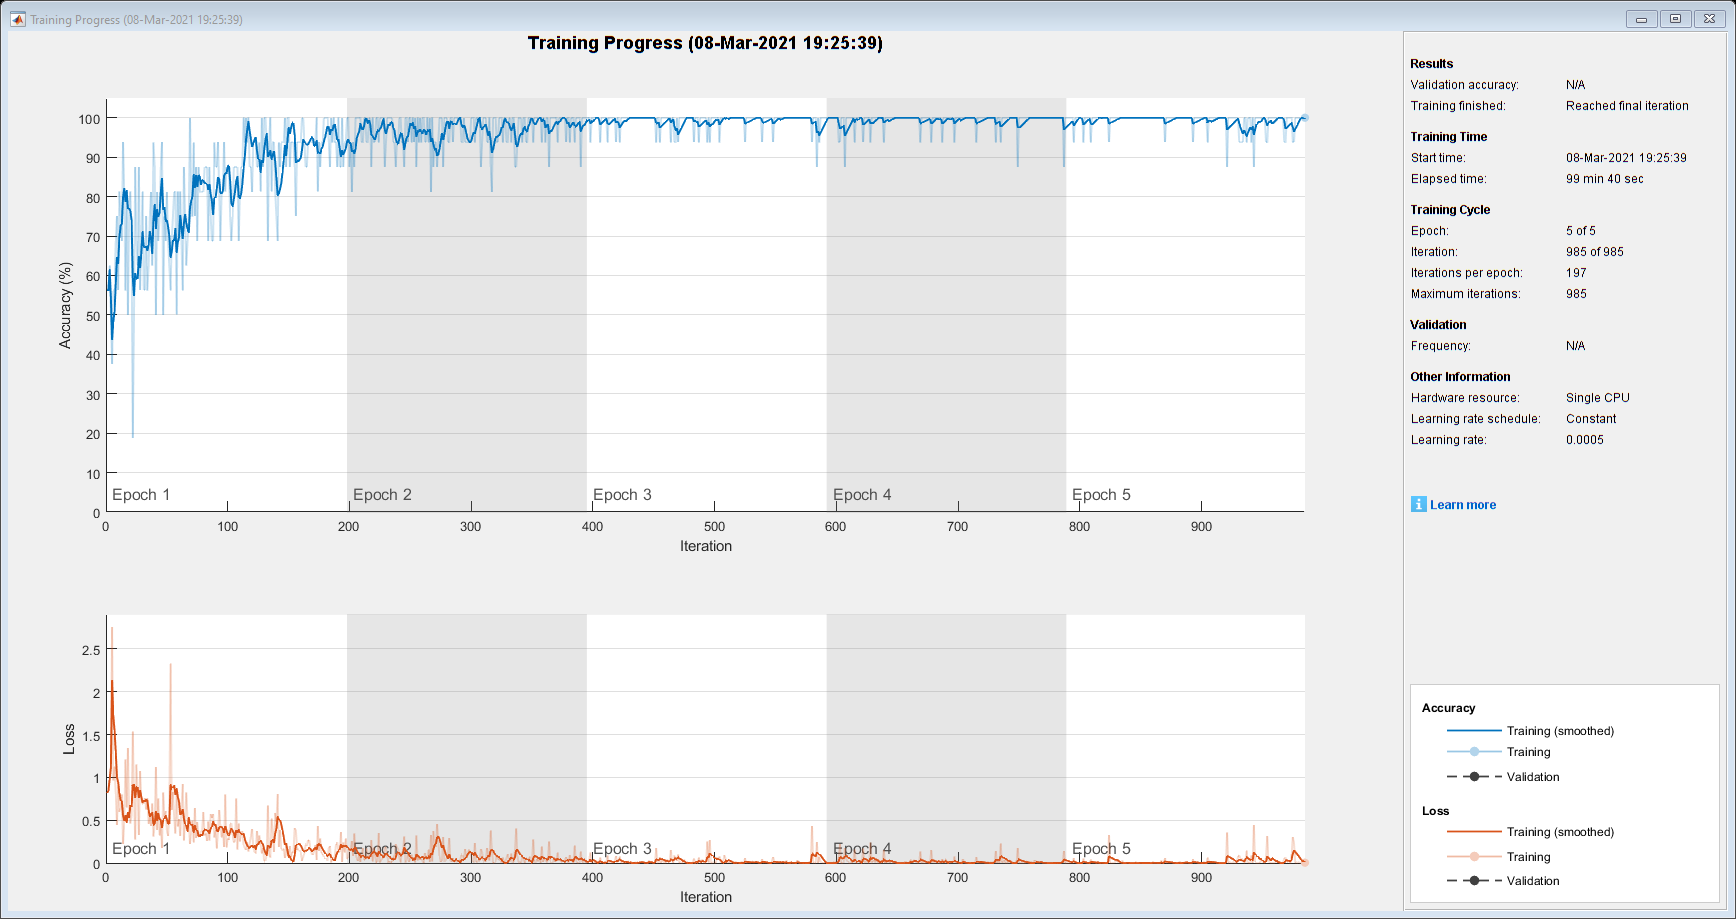

[net,info] = trainNetwork(Train_aug, lgraph, options);

## Prediction on Test

True_label = testSet.Labels;
testpreds = classify(net,Test_aug);

## Performance

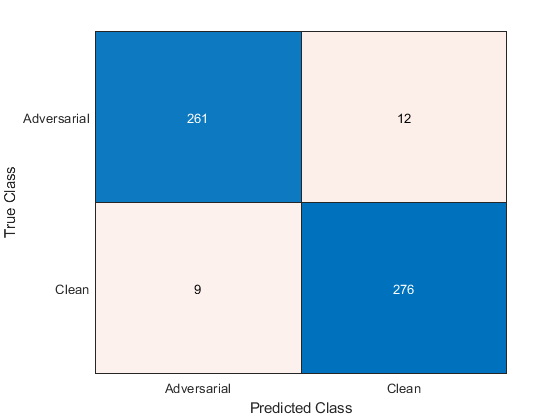

Accuracy = sum(True_label == testpreds)/numel(testpreds);
confusionchart(True_label, testpreds)

disp(Accuracy);

    0.9624




T = readtable('sampleSubmission.csv','Delimiter',',');
ids = T.Fingerprint;

preds_2 = {};
for i=1:numel(ids)
    imds = augmentedImageDatastore(imageSize,imageDatastore(['Test' filesep  ids{i}]));
    preds_2{end +1} = char(classify(net, imds)); 
end
submission = table(ids, preds_2', 'VariableNames', {'Fingerprint', 'Class'});
writetable(submission, 'SubmissionAlexNetMatlab_NoAug.csv','Delimiter', ',');
